# **Astrophotography : Pleiades Star Cluster**

# **Siddharth Raj Gupta**

The code takes long time to run, hence for convience, please load the parameters from work_values.mat

clc; clear all;
load('work_values.mat');
warning('off','all')

The images supplied are DNG and require extra work to be read in MATLAB. The following code will read these files into MATLAB array called raw and will also create metadata about each image. The code also crops the image into meanigful area which contains required information. 

filename = 'IMG_0914.dng'; % Put the name of 1st file here

warning off MATLAB:tifflib:TIFFReadDirectory:libraryWarning
t = Tiff(filename,'r');
offsets = getTag(t,'SubIFD');
setSubDirectory(t,offsets(1));

raw = read(t); % Create variable ’raw’, the Bayer CFA data
close(t);
img0 = raw;

The 1st image has been loaded. Now the rest of the images are registered with each other using MATLAB inbuilt imregister command. Since the images are captured using the same camera, it is advantageous to use monomodal argument for registering the images along with translation command. This is done by calling each image in a loop and registering it with previously registered image. 

[optimizer,metric] = imregconfig('multimodal');

for i =915:936

    filename = ['IMG_0' num2str(i) '.dng']; % Put file name here
    warning off MATLAB:tifflib:TIFFReadDirectory:libraryWarning
    t = Tiff(filename,'r');
    offsets = getTag(t,'SubIFD');
    setSubDirectory(t,offsets(1));

    raw = read(t); % Create variable     raw’, the Bayer CFA data
    close(t);
    img = raw;
    y = imregister(img,img0,'translation',optimizer,metric);
    img0 = y;
    
end

Cropping the image in desired region of useful information

meta_info = imfinfo(filename);
% Crop to only valid pixels
x_origin = meta_info.SubIFDs{1}.ActiveArea(2)+1; % +1 due to MATLAB indexing
width = meta_info.SubIFDs{1}.DefaultCropSize(1);
y_origin = meta_info.SubIFDs{1}.ActiveArea(1)+1;
height = meta_info.SubIFDs{1}.DefaultCropSize(2);
raw = double(raw(y_origin:y_origin+height-1,x_origin:x_origin+width-1));

The master images are of different sizes as compared to the raw image. Hence padding the raw image to make it equal in size with the master images.

raw(3745:3753,5617:5634) = 65535;

Performing calibration by subtracting dark and then dividing it by the difference of flat and bias. This removes all the camera irregularities from the image.

Xdark = imread('MASTERDARK_5m_1600ISO_34F_11.23.17.tif');
Xbias = imread('MASTERBIAS_5DmII_6.26.16.tif');
Xflat = imread('MASTERFLAT_Pleiades_11.23.17.tif');
               
raw_dark =  double(raw) - double(Xdark);
raw_flat = raw_dark./abs(double(Xflat)-(double(Xbias)));
disp('Raw image after calibration and registration');

Raw image after calibration and registration


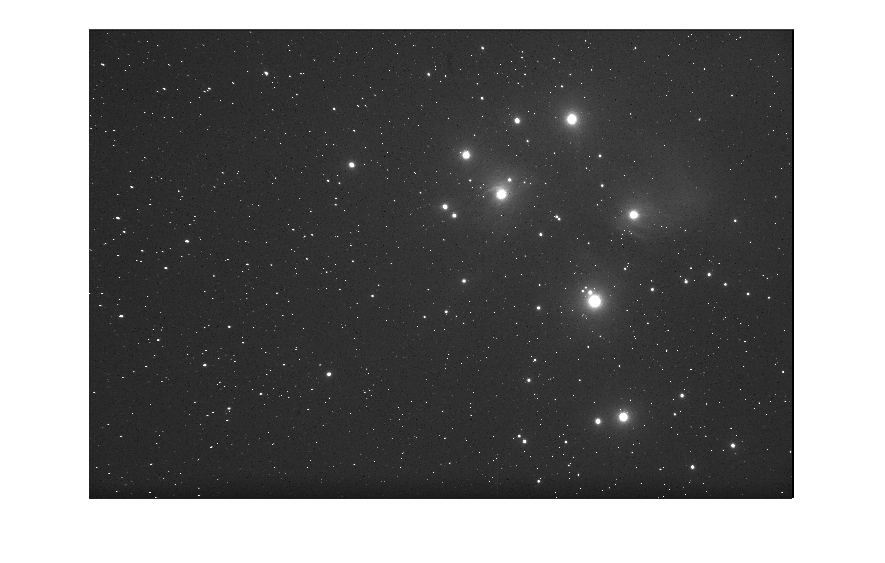

imshow(raw_flat);

Now this will act as the starting image on which all the modifications will be carried out to see improvements.

  Starting with smoothing the image using 7x7 filter

H = ones(7,7)/49;
X = conv2(raw_flat*65535,H,'same');
disp('Image after smoothing');

Image after smoothing


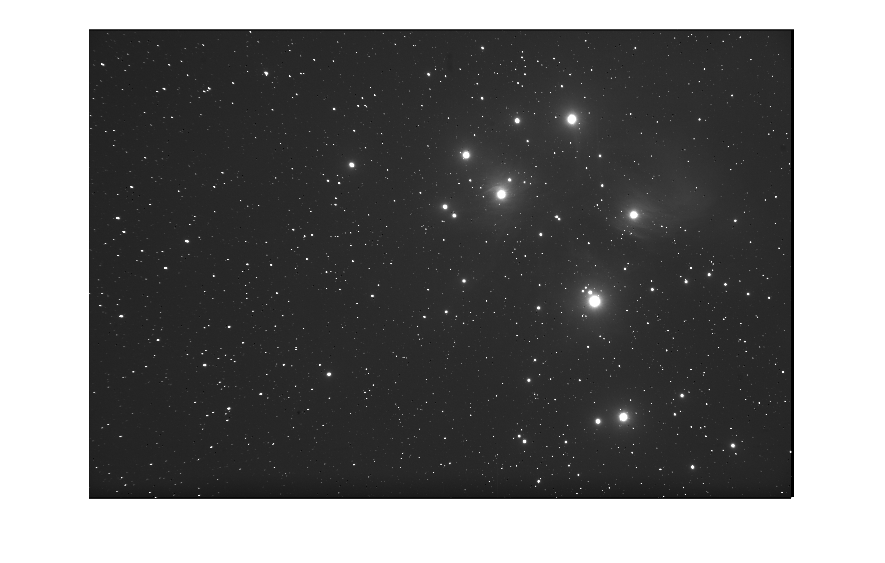

imshow(uint16(X));

Next, lets do demosaicing using rggb Bayer filter. The reason for using filter is to have reduced region with red color and more with blue or white color. As red affects and white protects.

X = demosaic(uint16(X),'rggb');
disp('Image after demosaicing using rggb Bayer filter');

Image after demosaicing using rggb Bayer filter


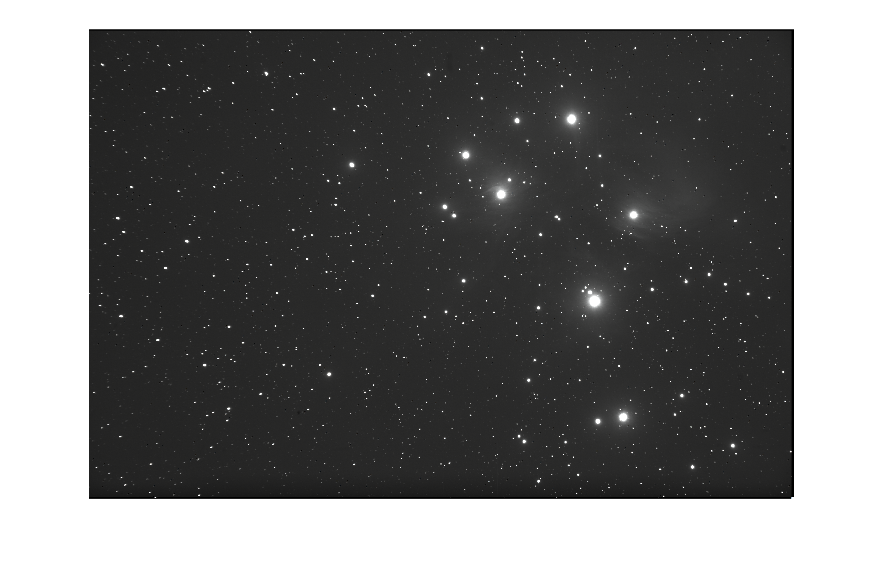

imshow(X);

Now we have the correct Bayer filter applied, lets further enhance the image using histogram equalisation. I tried to match the histogram of a targeted image color by color layer. The target image is as follows - 

Y = imread('IUs0Y6u8wXmNNPrd2nvy2N0UFv937Kq_1vKt0fTL6Fs.jpg');
disp('Target image');

Target image


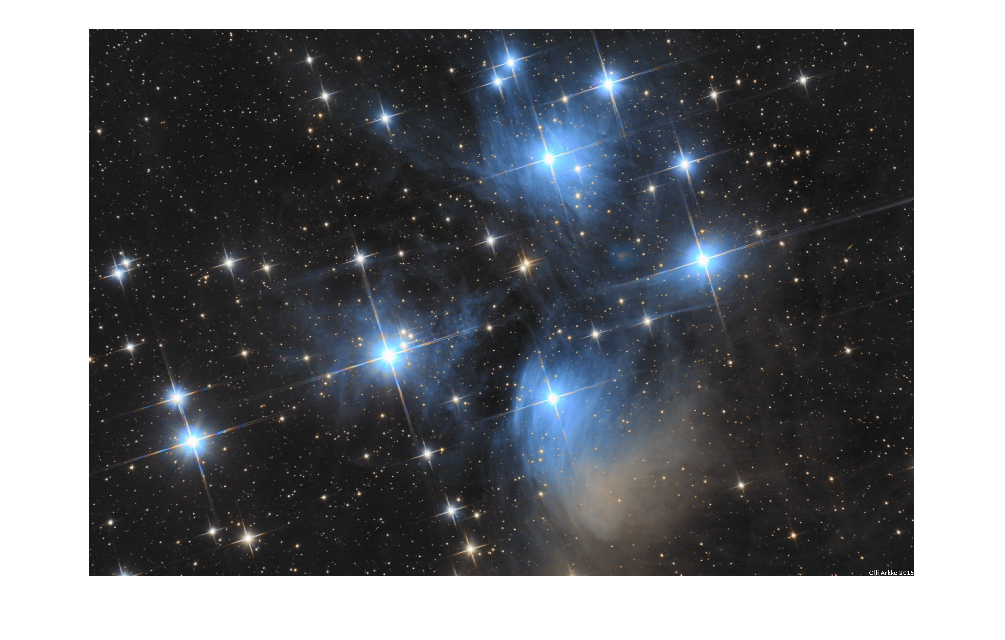

imshow(Y);

Seprating the color channel for our image and target image.

Xr = X(:,:,1);
Xg = X(:,:,2);
Xb = X(:,:,3);
Yr = Y(:,:,1);
Yg = Y(:,:,2);
Yb = Y(:,:,3);

Studying the histogram and cummilative distribution in the target image

eps =0.01;

%red color
H2Xr=hist(double(Yr(:))/255*65535,[0:65535]);
list = find(H2Xr(:)==0); H2Xr(list)=eps;
C2Xr = cumsum(H2Xr); C2Xr = C2Xr/max(C2Xr);

%green color
H2Xg=hist(double(Yg(:))/255*65535,[0:65535]);
list = find(H2Xg(:)==0); H2Xg(list)=eps;
C2Xg = cumsum(H2Xg); C2Xg = C2Xg/max(C2Xg);

%blue color
H2Xb=hist(double(Yb(:))/255*65535,[0:65535]);
list = find(H2Xb(:)==0); H2Xb(list)=eps;
C2Xb = cumsum(H2Xb); C2Xb = C2Xb/max(C2Xb);

disp('target image color distribution');

target image color distribution


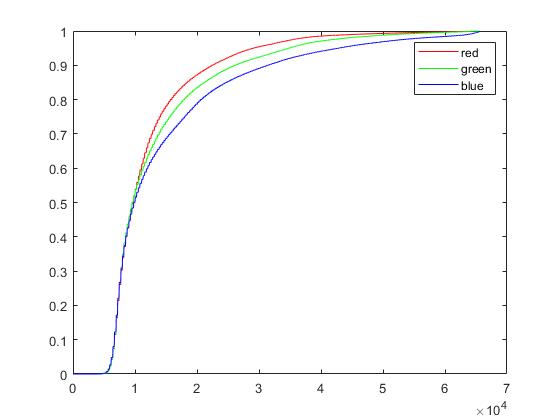

plot(C2Xr','-r');hold on
plot(C2Xg','-g');hold on
plot(C2Xb','-b');hold on
legend('red','green','blue');

Studying the histogram and cummilative distribution in the raw image

%red color
H1Xr=hist((Xr(:)),[0:65535]);
list = find(H1Xr(:)==0); H1Xr(list)=eps;
C1Xr = cumsum(H1Xr); C1Xr = C1Xr/max(C1Xr);

%green color
H1Xg=hist((Xg(:)),[0:65535]);
list = find(H1Xg(:)==0); H1Xg(list)=eps;
C1Xg = cumsum(H1Xg); C1Xg = C1Xg/max(C1Xg);

%blue color
H1Xb=hist((Xb(:)),[0:65535]);
list = find(H1Xb(:)==0); H1Xb(list)=eps;
C1Xb = cumsum(H1Xb); C1Xb = C1Xb/max(C1Xb);

disp('raw image color distribution');

raw image color distribution


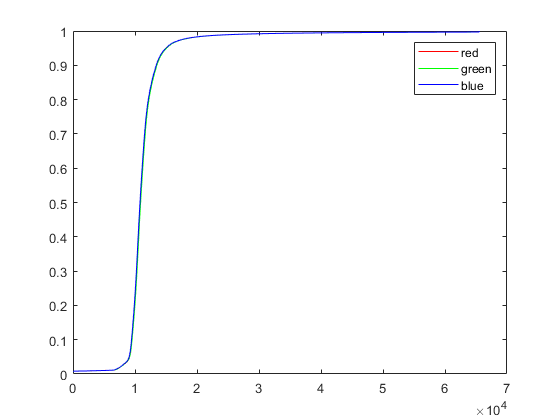

plot(C1Xr','-r');hold on
plot(C1Xg','-g');hold on
plot(C1Xb','-b');
legend('red','green','blue');

Performing interpolations 

%red color
nr = interp1(unique(C2Xr),(0:65535),C1Xr,'linear',0);
Tr = uint16(nr);

%green color
ng = interp1(unique(C2Xg),(0:65535),C1Xg,'linear',0);
Tg = uint16(ng);

%blue color
nb = interp1(unique(C2Xb),(0:65535),C1Xb,'linear',0);
Tb = uint16(nb);

disp('Interpolations of different color based on target image');

Interpolations of different color based on target image


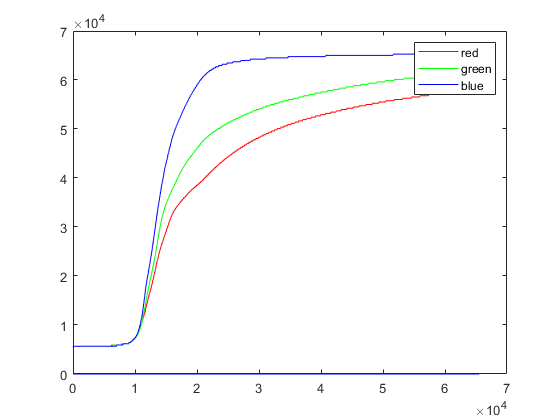

plot(Tr,'-r');hold on
plot(Tg,'-g');hold on
plot(Tb,'-b');
legend('red','green','blue');

The transformations are multiplied by some factors in order to create different impressive color patterns- 

%red layer
X(:,:,1) = Tr(uint16(Xr+1))*1.4;
%green layer
X(:,:,2) = Tg(uint16(Xg+1))*1.2;
%blue layer
X(:,:,3) = Tb(uint16(Xb+1))*1.8;

Final improvisation

A3X= X;
H3X = hist(double(A3X(:)),[0:2^16-1]);
C3X = cumsum(H3X); C3X = C3X/max(C3X);
disp('Final image cumulative distribution ');

Final image cumulative distribution 


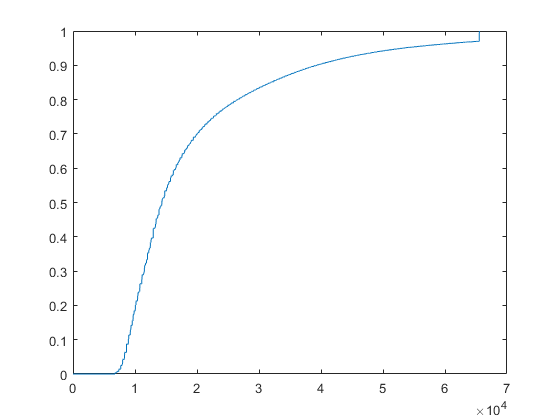

plot(C3X');

A4X = A3X(1:3600,1:5617,1:3);
disp('Final Image')

Final Image


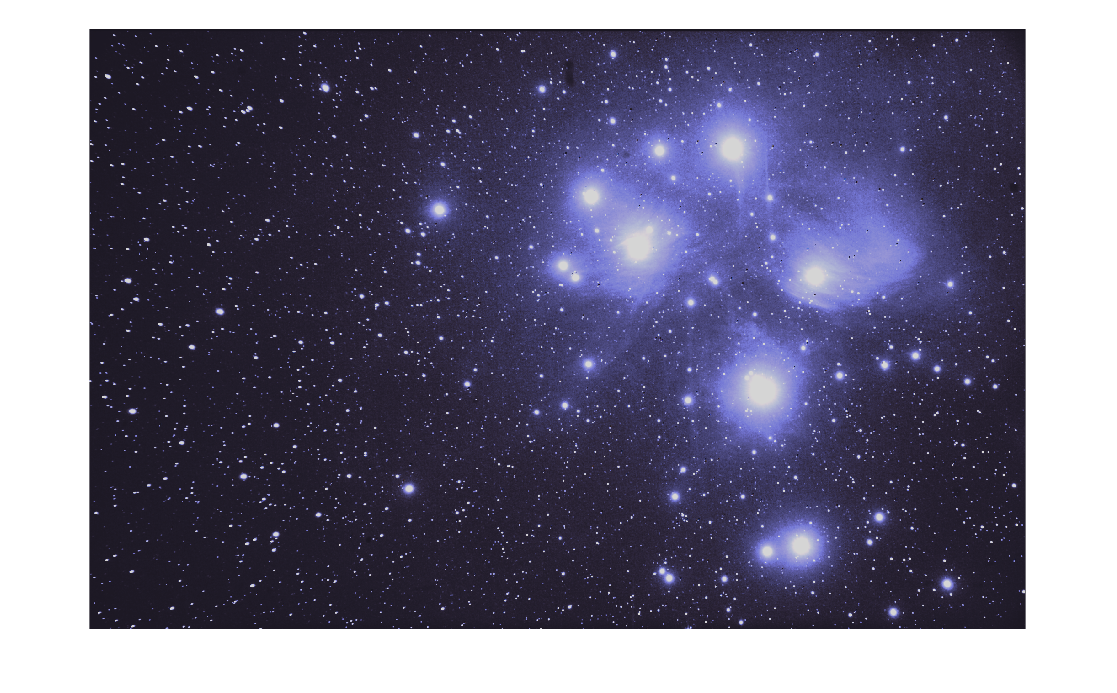

imshow(A4X/1.2)